clf; 

% One Way Code 

one_way = csvread("exp3_one_way_I1.csv");

IinOneWay = -1.*one_way(:,1);
IoutOneWay = one_way(:,2);

oneWayPolyFit = polyfit(IinOneWay(1:550),IoutOneWay(1:550), 1);

oneWayFit = oneWayPolyFit(1).*IinOneWay(1:550) + oneWayPolyFit(2); 

%disp(oneWayPolyFit(1))

% Two Way Code 

two_way = csvread('exp3_two_way.csv');

IinTwoWay = two_way(:,1);
IoutTwoWay = -1.* two_way(:,2);

twoWayPolyFit = polyfit(IinTwoWay(1:450),IoutTwoWay(1:450), 1);

twoWayFit = (twoWayPolyFit(1).*IinTwoWay) + twoWayPolyFit(2); 

%disp(twoWayPolyFit(1))


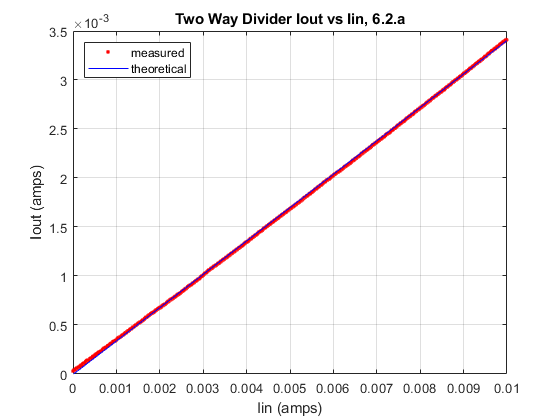

% Plotting things 

figure 
h = plot(IinOneWay, IoutOneWay, 'r.'); 
grid on
hold on; 
plot(IinOneWay(1:550), oneWayFit, 'b');
xlim([0 0.01])
ylim([0 3.5e-3])
%title("One Way Iout vs. Iin")
title("Two Way Divider Iout vs Iin, 6.2.a")
xlabel('Iin (amps)')
ylabel('Iout (amps)')
legend('measured', 'theoretical', 'Location', 'northwest') 
set(h,'markersize',8)
hold off; 

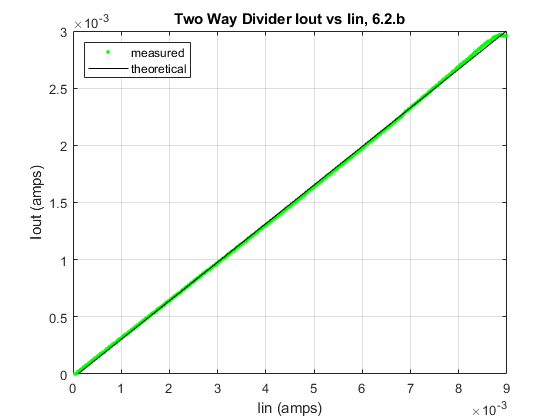


figure
d = plot(IinTwoWay,IoutTwoWay, 'g.');
xlim([0 0.009])
ylim([0 3e-3])
grid on
hold on
plot(IinTwoWay(1:450), twoWayFit(1:450), 'k')
set(d,'markersize',8)
%title('Two Way Iout vs Iin')
title("Two Way Divider Iout vs Iin, 6.2.b")
xlabel('Iin (amps)')
ylabel('Iout (amps)')
legend('measured', 'theoretical', 'Location', 'northwest')